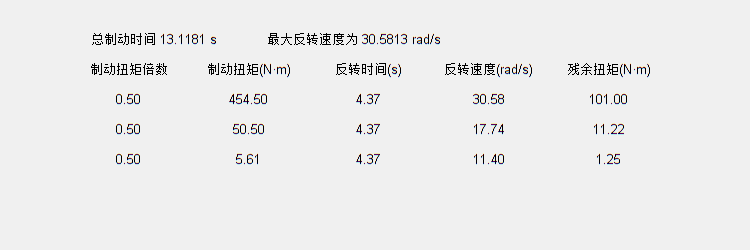

% 假设这些是你的数据
tt3 = 13.1181; % 总制动时间
vv3 = 30.5813; % 最大反转速度
mm = [0.50, 0.50, 0.50]; % 制动扭矩倍数
Mt = [454.50, 50.50, 5.61]; % 制动扭矩
tt = [4.37, 4.37, 4.37]; % 反转时间
vv = [30.58, 17.74, 11.40]; % 反转速度
MM_re = [101.00, 11.22, 1.25]; % 残余扭矩

% 初始化单元数组
data = {};

% 添加表头
data{1, 1} = '制动扭矩倍数';
data{1, 2} = '制动扭矩(N·m)';
data{1, 3} = '反转时间(s)';
data{1, 4} = '反转速度(rad/s)';
data{1, 5} = '残余扭矩(N·m)';

% 添加数据行
for i = 1:length(mm)
    data{1+i, 1} = num2str(mm(i), '%.2f');
    data{1+i, 2} = num2str(Mt(i), '%.2f');
    data{1+i, 3} = num2str(tt(i), '%.2f');
    data{1+i, 4} = num2str(vv(i), '%.2f');
    data{1+i, 5} = num2str(MM_re(i), '%.2f');
end

% 将总制动时间和最大反转速度添加到另一个单元数组中
data2 = {sprintf('总制动时间 %.4f s', tt3), sprintf('最大反转速度为 %.4f rad/s', vv3)};



% 参数名称
titles = {'制动扭矩倍数', '制动扭矩(N·m)', '反转时间(s)', '反转速度(rad/s)', '残余扭矩(N·m)'};

% 创建图形窗口
fig = figure('Position', [400, 300, 750, 250], 'Name', '参数显示');
% Notice：数值参数左到右分别为窗口中心的在屏幕的x，y坐标，窗口的长宽






%创建文本控件显示数据
for i = 1:size(data, 1)
    for j = 1:size(data, 2)
        txt_data = uicontrol('Style', 'text', ...
            'Position', [70 + (j-1)*120, 170 + (i-1)*(-30), 120, 20], ... % 第2个数值的步进值最好与第三个相等
            'FontSize', 10, ...
            'HorizontalAlignment', 'center', ...
            'String', data{i, j});
    end
end

for i = 1:2
     txt_data = uicontrol('Style', 'text', ...
            'Position', [55 + (i-1)*200, 200, 200, 20], ... % 第2个数值的步进值最好与第三个相等
            'FontSize', 10, ...
            'HorizontalAlignment', 'center', ...
            'String', data2{i});
end



% Notice：数值参数左到右对应着元素在窗口的x，y坐标，以及元素的长宽大小
% Notice：此角度上常数项具有新的几何意义
% Notice：数值之间有大小包容关系原则、不能瞎填写
% Notice:unicontrol控件连续展示参数文本时可以手动销毁上一次展示内容也可以
%        同窗口继续展示文本

% Notice：(ax,by)光标，当(a>0&b>0)时表示从左到右，从下到上移动
% 当(a>0&b<0)时表示从左到右，从上到下移动，该光标可能是读取光标也可能是放置光标
% 研究课题：figure组件内元素的绝对摆放和相对摆放

